clear all; close all; clc

Drone control Hewer vs. RL toolbox

% Drone 6DOF (six degrees of freedom) linearized and discretized model
g=9.81; % acceleration of gravity; 
m=0.506; % [kg] quadcopter mass;
l=0.235; % [m]
Ix=8.11858*10^(-5); % [kg m^2] inertia for 
Iy=8.11858*10^(-5); % [kg m^2] inertia for yb
Iz=6.112233*10^(-5); % [kg m^2] inertia for zb
b1=l/Ix; b2=l/Iy; b3=l/Iz;
Ac=[0 1 0 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 0;
   0 0 0 1 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 1 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 1 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 1 0 0;
   0 0 g 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 1;
   -g 0 0 0 0 0 0 0 0 0 0 0];
Bc=[0 0 0 0;
    0 b1 0 0;
    0 0 0 0;
    0 0 b2 0;
    0 0 0 0;
    0 0 0 b3;
    0 0 0 0;
    1/m 0 0 0;
    0 0 0 0;
    0 0 0 0;
    0 0 0 0;
    0 0 0 0];
n = size(Ac,1); m = size(Bc,2); 
R1=eye(n); R2=eye(m);
Q = R1; R = R2;
Cc=eye(n);
% Cc = [1 0 0 0 0 0 0 0 0 0 0 0;
%       0 0 1 0 0 0 0 0 0 0 0 0;
%       0 0 0 0 1 0 0 0 0 0 0 0;
%       0 0 0 0 0 0 1 0 0 0 0 0;
%       0 0 0 0 0 0 0 0 1 0 0 0; 
%       0 0 0 0 0 0 0 0 0 0 1 0]; 
% r = size(Cc,1)
Dc = zeros(n,m);

Discretization

sysc = ss(Ac,Bc,Cc,Dc);
Ts = 0.01;
sysd = c2d(sysc,Ts);
% A = sysd.A; B = sysd.B; C = sysd.C; D = sysd.D;
[A,B,C,D]=ssdata(sysd);
x0 = 0.5*ones(n,1);

Test for controllability and observability

CO=ctrb(A,B);
rankCO=rank(CO) % finds the rank of the controllability matrix

rankCO = 12

% the rank is equal to n (system order) implies controllability
OM=obsv(A,C);
rOM=rank(OM) % rank equal to n implies observability

rOM = 12

Direct solution of the optimal LQ problem

[Fopt,P]=dlqr(A,B,R1,R2);
Jopt=0.5*x0'*P*x0

Jopt = 276.1077

***Reinforcement Learning Solution:***

ev=eig(A);
% % Since A is asymptotically stable (all eigenvalues inside of unit circle
% % we can use F0 = 0 (pay attention to the dimension of this zero)
% F0=zeros(2,4)
% In general, to find F0 that stabilize the system, 
% we can use the MATLAB function place that finds the feedback
% matrix that places the closed loo (A-B*F0) ev in the desired locations
% lambda_desired=[-0.5; 0.2; -0.1+j*0.5 -0.1-j*0.5] can use complex conjugate ev
% F0=place(A,B,lambda_desired);
% check ev of (A-B*F0); evF0=eig(A-B*F0);
lambda_desired=0.1*[-1 -2 -3 -4 -5 -6 -7 -8 -9 0.5 8.5 7.5];
% lambda_desired = -0.1*ones(1,n);
F0=place(A,B,lambda_desired);

***Hewer's Reinforcer***

    
$$P_i = \big(A-BF_{i-1} \big)^{\mathrm{T}}P_i \big(A-BF_{i-1} \big) + F_{i-1}^{\mathrm{T}}RF_{i-1} +Q, \qquad i=1,2,3,\cdots \\
F_{i} = -\big( R + B^{\mathrm{T}}P_iB \big)^{-1} B^{\mathrm{T}}P_iA, \qquad \mathrm{with}\ F_0\ \mathrm{stabilizing} \ |\lambda_j\big(A-BF_0 \big)| <1$$


% Set-up total iteration
Iter=8

Iter = 8

Ji=0;
% Pi(:) = [];
% Policy iterations of the Hewer algorithm
Pi{1} = dlyap((A-B*F0)',R1+F0'*R2*F0);
F{1} = inv(R2+B'*Pi{1}*B)*B'*Pi{1}*A;
Ji(1)=0.5*x0'*Pi{1}*x0;
Error(1) = norm((A-B*F{1})'*Pi{1}*(A-B*F{1})-Pi{1}+R1+F{1}'*R2*F{1});
for i=2:Iter
    Pi{i}=dlyap((A-B*F{i-1})',R1+F{i-1}'*R2*F{i-1});
    i;
    Ji(i)=0.5*x0'*Pi{i}*x0;
    F{i}=inv(R2+B'*Pi{i}*B)*B'*Pi{i}*A;
    Error(i) = norm((A-B*F{i})'*Pi{i}*(A-B*F{i})-Pi{i}+R1+F{i}'*R2*F{i});
% Calling Simulink
    model=sim(Drone_12);
    time_itr(1:length(model.t),i) = model.t;
    X(i,1:length(model.t),:) = model.x(:,:); % i-th iter, step, x(j)
    U(i,1:length(model.t),:) = model.u(:,:);
end
F{i} = Fopt;
model=sim(Drone_12);
% Plotting approximate and optimal state trajectories
% time_itr(1:length(model.t),i) = model.t;
X_opt(1:length(model.t),:) = model.x(:,:); % i-th iter, step, x(j)
U_opt(1:length(model.t),:) = model.u(:,:);

***Plotting the obtained results:  %%% localization? visual?***

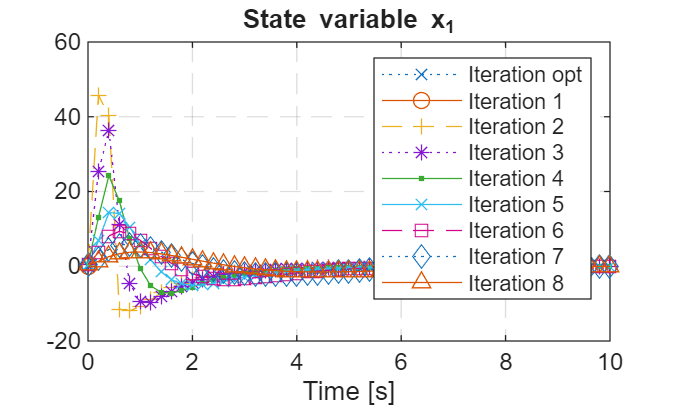

markers = {'o', '+', '*', '.', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
lineStyles = {'-', '--', ':', '-.'};

figure (1)
Iname_1 = sprintf('Iteration opt');
plot(time_itr(:,1),X_opt(:,1),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_1)
 for i=1:Iter
     hold on
     Iname_1 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,1),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_1)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_1')
legend;

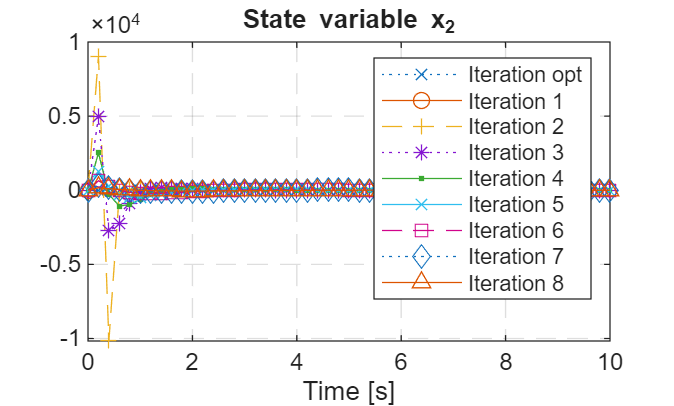

figure (2)
Iname_2 = sprintf('Iteration opt');
plot(time_itr(:,2),X_opt(:,2),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_2)
 for i=1:Iter
     hold on
     Iname_2 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,2),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_2)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_2')
legend;

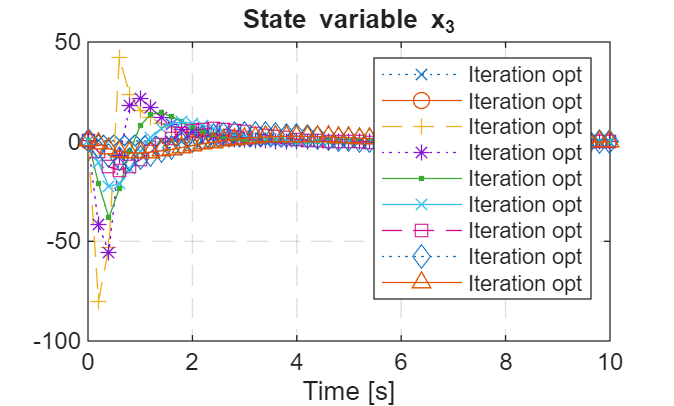

figure (3)
Iname_3 = sprintf('Iteration opt');
plot(time_itr(:,3),X_opt(:,3),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_3)
 for i=1:Iter
     hold on
     Iname_1 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,3),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_3)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_3')
legend;

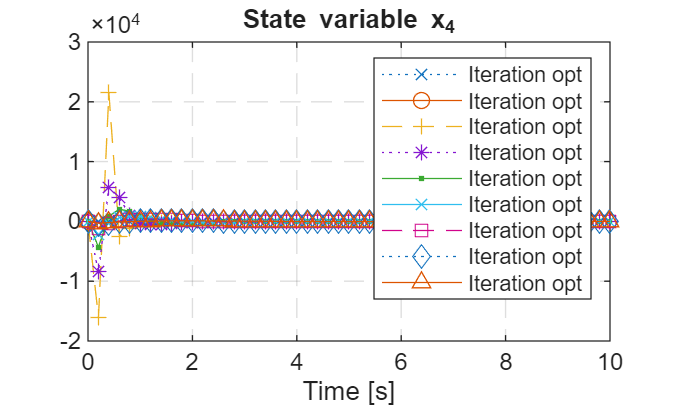

figure (4)
Iname_4 = sprintf('Iteration opt');
plot(time_itr(:,4),X_opt(:,4),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_4)
 for i=1:Iter
     hold on
     Iname_1 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,4),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_4)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_4')
legend;

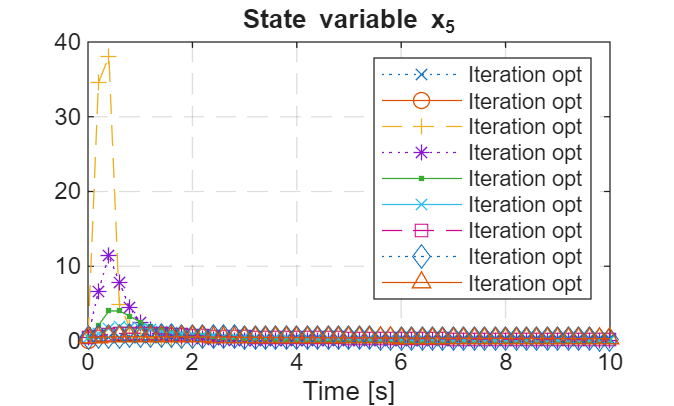

figure (5)
Iname_5 = sprintf('Iteration opt');
plot(time_itr(:,5),X_opt(:,5),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_5)
 for i=1:Iter
     hold on
     Iname_1 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,5),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_5)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_5')
legend;

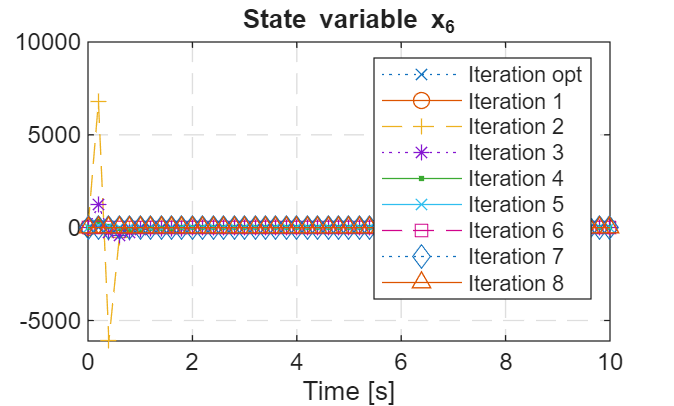


figure (6)
Iname_6 = sprintf('Iteration opt');
plot(time_itr(:,6),X_opt(:,6),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_6)
 for i=1:Iter
     hold on
     Iname_6 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,6),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_6)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_6')
legend;

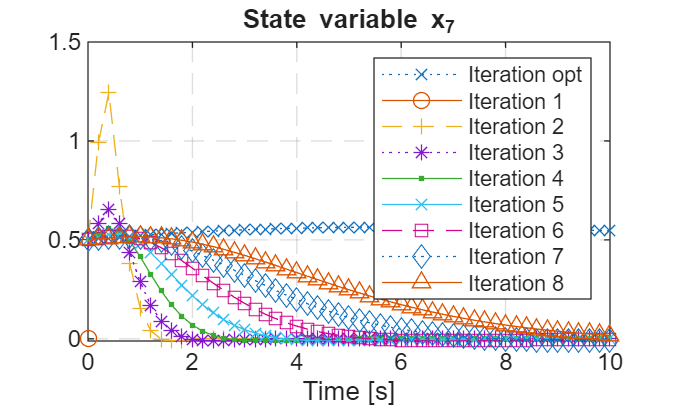

figure (7)
Iname_7 = sprintf('Iteration opt');
plot(time_itr(:,7),X_opt(:,7),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_7)
 for i=1:Iter
     hold on
     Iname_7 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,7),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_7)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_7')
legend;

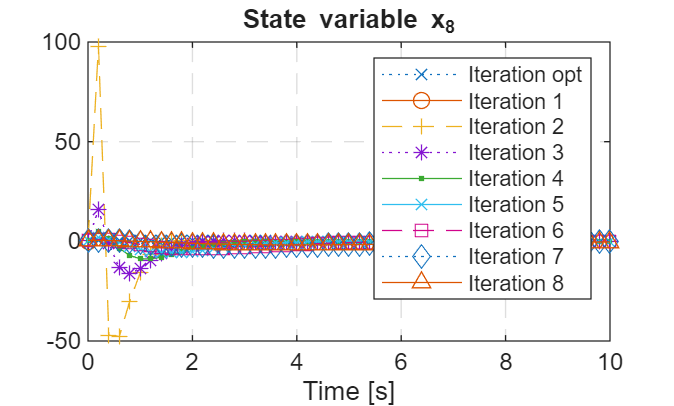

figure (8)
Iname_8 = sprintf('Iteration opt');
plot(time_itr(:,8),X_opt(:,8),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_8)
 for i=1:Iter
     hold on
     Iname_8 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),X(i,:,8),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_8)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('State variable x_8')
legend;

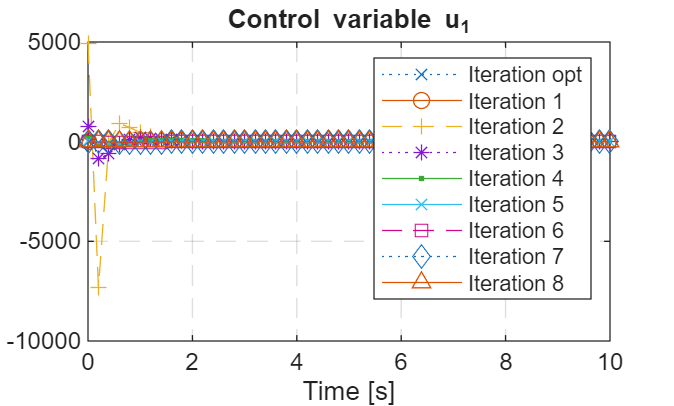


figure (9)
Iname_1 = sprintf('Iteration opt');
plot(time_itr(:,1),U_opt(:,1),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_1)
 for i=1:Iter
     hold on
     Iname_1 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),U(i,:,1),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_1)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('Control variable u_1')
legend;

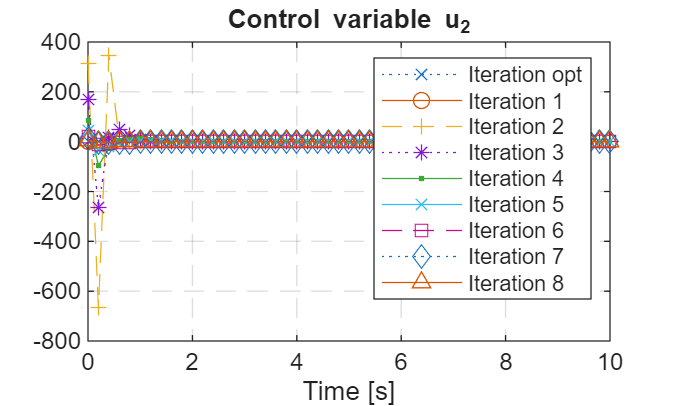


figure (10)
Iname_2 = sprintf('Iteration opt');
plot(time_itr(:,2),U_opt(:,2),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_2)
 for i=1:Iter
     hold on
     Iname_2 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),U(i,:,2),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_2)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('Control variable u_2')
legend;

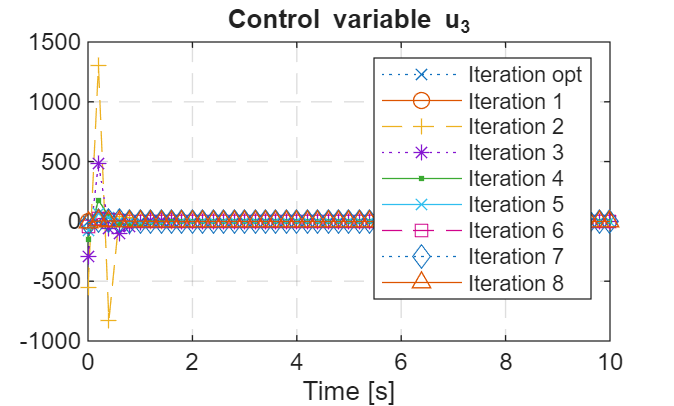

figure (11)
Iname_3 = sprintf('Iteration opt');
plot(time_itr(:,3),U_opt(:,3),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_3)
 for i=1:Iter
     hold on
     Iname_3 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),U(i,:,3),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_3)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('Control variable u_3')
legend;

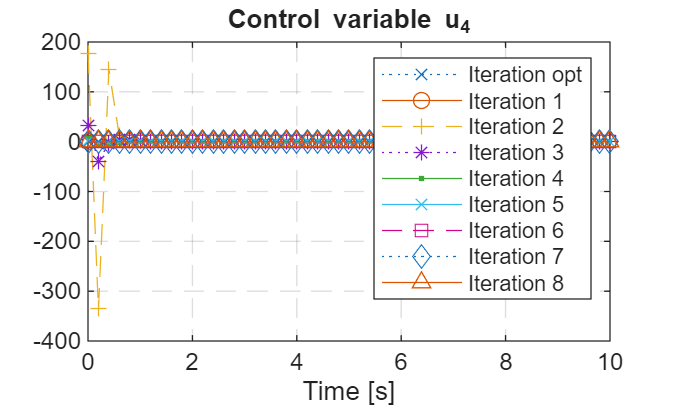

figure (12)
Iname_4 = sprintf('Iteration opt');
plot(time_itr(:,4),U_opt(:,4),'Marker','x' ,...
         'linestyle',':','DisplayName',Iname_4)
 for i=1:Iter
     hold on
     Iname_4 = sprintf('Iteration %d', i);
     plot(time_itr(:,i),U(i,:,4),'Marker',markers{mod(i,Iter+1)},...
         'linestyle',lineStyles{max(mod(i,4),1)},'DisplayName',Iname_4)  
 end
grid on
set(gca,'GridLineStyle','--')
xlabel('Time [s]');title('Control variable u_4')
legend;

***Further Study with RL toolbox:***

Environment set-up:

env = myDiscreteEnv(A,B,Q,R);
rng(0);

LQR agent creation:

agent = LQRCustomAgent(Q,R,F0);

'LQRCustomAgent' is used in Create and Train Custom LQR Agent.

%getActionInfo(agent)

% Set-up future reward discount factor
agent.Gamma = 0.8%0.8

% Set-up the number of data point to be collected before updating the critic
agent.EstimateNum = 80%80, 90

LQR agent training:

% Set-up training options
trainingOpts = rlTrainingOptions(...
    MaxEpisodes=10, ...
    MaxStepsPerEpisode=15, ...% 10
    Verbose=false);%, ...
   % Plots="training-progress");
% Training the agent
trainingStats = train(agent,env,trainingOpts);

LQR agent perfromance evaluation:

simOptions = rlSimulationOptions(MaxSteps=Iter);
experience = sim(env,agent,simOptions);
totalReward = abs(sum(experience.Reward))

Performance comparison:

Hewer_reinforcer_error = Ji(Iter) - Jopt
LQR_agent_error = totalReward - Jopt

Plot iteration-wise difference of gains 

figure (16)
% Plot the norm of the gain difference of the trained LQR agent and the optimal LQR solution
% Number of gain updates
len = agent.KUpdate;

% Initialize error vector
err = zeros(len,1);

% Fill elements
for i = 1:len
    err(i) = norm(agent.KBuffer{i}-Fopt);
end

% Plot logarithm of the error vector
plot(log10(err),'b*-','DisplayName','LQR Agent')
grid on
hold on

% Plot the norm of the gain difference of the Hewer reinforcer and the optimal LQR solution
err_h = zeros(Iter,1);
for i=1:Iter
    err_h(i) = norm(F{i}-Fopt);
end
plot(log10(err_h),'rx-','DisplayName','Hewer reinforcer')
hold on
legend
title("Log of gain difference")
xlabel("Number of updates/iterations")